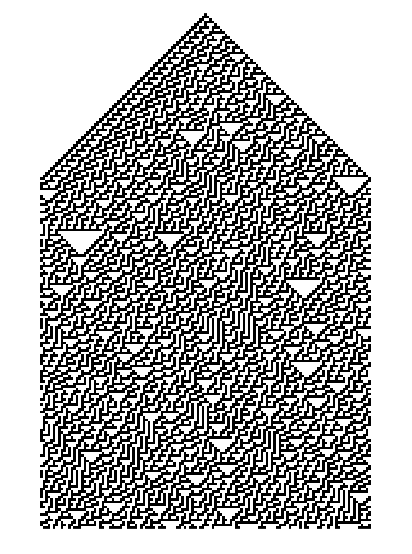

single_black_middle = [zeros(1, 64) 1 zeros(1, 64)];
visualize_rule30(single_black_middle, 200, 1)

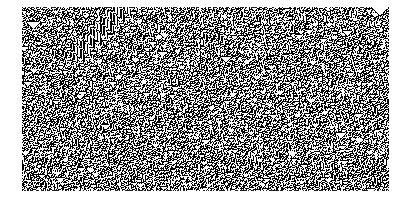

single_black_middle_wider = [zeros(1, 256) 1 zeros(1, 256)];
visualize_rule30(single_black_middle_wider, 256*2, 257)

rng_eca(0);
rng(0);
N = 10^5;
bins = 20;
data = rand_eca(1, N);
data_built_in = rand(1, N);

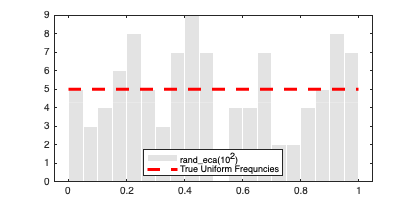

hist_vs_true_uniform(data(1:10^2), bins, "rand\_eca(10^2)");

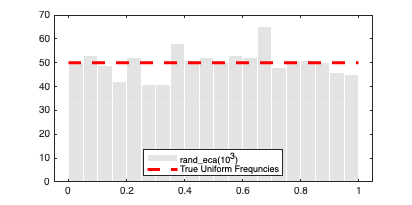

hist_vs_true_uniform(data(1:10^3), bins, "rand\_eca(10^3)");

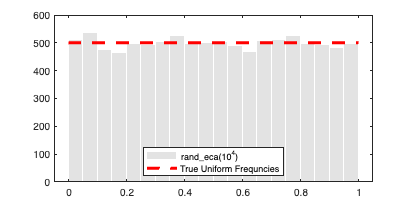

hist_vs_true_uniform(data(1:10^4), bins, "rand\_eca(10^4)");

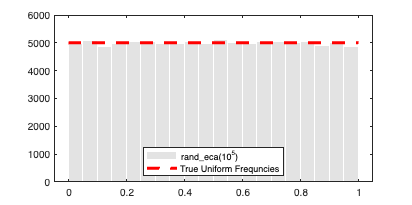

hist_vs_true_uniform(data(1:10^5), bins, "rand\_eca(10^5)");

fprintf("rand_eca test")

rand_eca test

[observed, theoretical, p_value] = chi_squared_test(data, bins)

observed =   15.243487062771049


theoretical =   30.143527205646155


p_value =    0.707001328711540


fprintf("built-in rand test")

built-in rand test

[observed, theoretical, p_value] = chi_squared_test(data_built_in, bins)

observed =   23.846658639311908


theoretical =   30.143527205646155


p_value =    0.202100244683098
